# Hobbing - Entwicklung der Mathematik

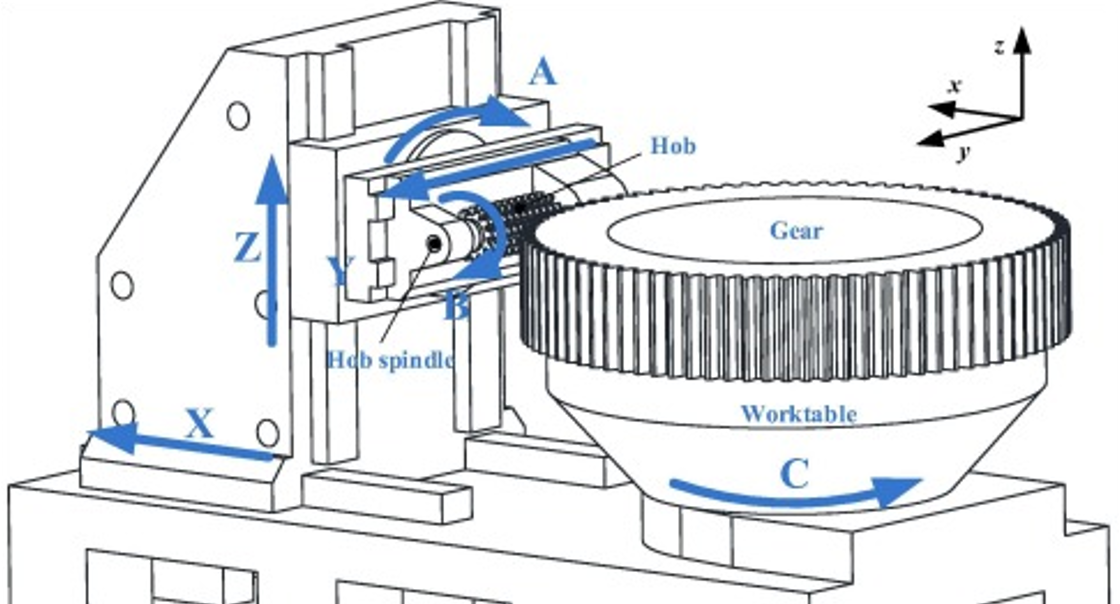

## Transformationsmatrizen

### Rotationen

#### B-Achse

Rotation um B-Achse ist um Koordinatensystem y-Achse

syms B
R_B = axang2rtm('y',-B)

$$R\_B = \left(\begin{array}{cccc} \cos\left(B\right) & 0 & -\sin\left(B\right) & 0\\ 0 & 1 & 0 & 0\\ \sin\left(B\right) & 0 & \cos\left(B\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### A-Achse

Rotation um A-Achse ist um Koordinatensystem x-Achse

syms A
R_A = axang2rtm('x',A)

$$R\_A = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(A\right) & -\sin\left(A\right) & 0\\ 0 & \sin\left(A\right) & \cos\left(A\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### C-Achse

Rotation um C-Achse ist um Koordinatensystem z-Achse

Winkel C ist Funktion der Werkzeugrotation und Werkstückvorschub (als Vorfaktor)

- Werkstückvorschub (f_WSTrad) ist Übersetzungsverhältnis des Schneckengetriebes

- Übersetzungsverhältnis: Anzahl Schneidreihen zu Anzahl Zähne am Bauteil: $i = \frac{n_{Schneidreihen}}{n_{Zähne}}$

- Vorzeichen des Vorschubes ergibt sich aus der Drehrichtung der Werkzeugspirale (Rechtsgewinde positiv)

syms C ga f_WSTrad
C = f_WSTrad * B + ga

$$C = \mathrm{ga}+B\,f_{\mathrm{WSTrad}}$$

R_Cga = axang2rtm('z', C)

$$R\_Cga = \left(\begin{array}{cccc} \cos\left(\mathrm{ga}+B\,f_{\mathrm{WSTrad}}\right) & -\sin\left(\mathrm{ga}+B\,f_{\mathrm{WSTrad}}\right) & 0 & 0\\ \sin\left(\mathrm{ga}+B\,f_{\mathrm{WSTrad}}\right) & \cos\left(\mathrm{ga}+B\,f_{\mathrm{WSTrad}}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Rotiertes Werkzeugkoordinatensystem

R_Wkz = fix(axang2rtm('x',pi/2))

R_Wkz =      1     0     0     0
     0     0    -1     0
     0     1     0     0
     0     0     0     1


### Translationen

#### Translation der Y-Achse mit shift

syms y fY_WZrad Y_shift
T_Ys = trvecHomTform('y',y + fY_WZrad*B + Y_shift)

$$T\_Ys = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & Y_{\mathrm{shift}}+y+B\,{\mathrm{fY}}_{\mathrm{WZrad}}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Translation der x- und z-Achse

saubere XZ-Achsen TM:

syms x z
T_XZ = trvecHomTform('x',x,'z',z)

$$T\_XZ = \left(\begin{array}{cccc} 1 & 0 & 0 & x\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & z\\ 0 & 0 & 0 & 1 \end{array}\right)$$

TM für XZ-Achsen Vorschübe:

syms fZ_WZrad fX_WZrad
T_XZf = trvecHomTform('x',fX_WZrad*B,'z',fZ_WZrad*B)

$$T\_XZf = \left(\begin{array}{cccc} 1 & 0 & 0 & B\,{\mathrm{fX}}_{\mathrm{WZrad}}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & B\,{\mathrm{fZ}}_{\mathrm{WZrad}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

TM für die Offsets des Werkstückkoordinatensystems

Versatz Achsen zu Null C

syms a b c
T_offs = trvecHomTform([a,b,c])

$$T\_offs = \left(\begin{array}{cccc} 1 & 0 & 0 & a\\ 0 & 1 & 0 & b\\ 0 & 0 & 1 & c\\ 0 & 0 & 0 & 1 \end{array}\right)$$

neue, gesamte XZ-Transformationsmatrix, T_offs geht invers ein, weil es auf der linken Seite steht

T_XZ = T_XZ * T_XZf

$$T\_XZ = \left(\begin{array}{cccc} 1 & 0 & 0 & x+B\,{\mathrm{fX}}_{\mathrm{WZrad}}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & z+B\,{\mathrm{fZ}}_{\mathrm{WZrad}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Transformationsmatrix Werkzueg nach Maschine

- Reihenfolge ergibt sich mit Linksmultiplikation durch die kinematische Kette ausgehend vom Werkzeug

- damit ergibt sich die Richtung der TM: von Werkzeug-frame in das Maschinen(bett)-frame

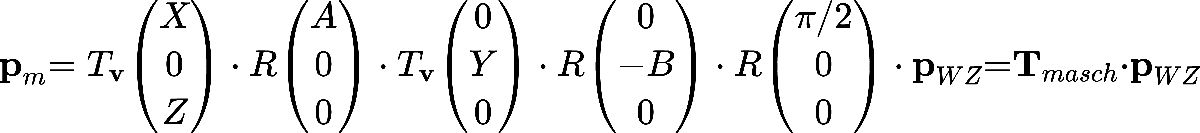

Tm_Wkz = T_XZ * R_A * T_Ys * R_B * R_Wkz;

### Transformationsmatrix Werkstück nach Maschine

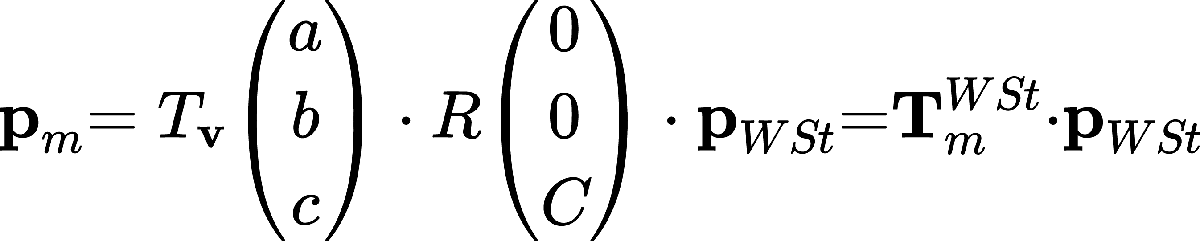

Tm_Wst = R_Cga * T_offs

$$Tm\_Wst = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & a\,\sigma_{2}-b\,\sigma_{1}\\ \sigma_{1} & \sigma_{2} & 0 & a\,\sigma_{1}+b\,\sigma_{2}\\ 0 & 0 & 1 & c\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\mathrm{ga}+B\,f_{\mathrm{WSTrad}}\right)\\ \sigma_{2}=\cos\left(\mathrm{ga}+B\,f_{\mathrm{WSTrad}}\right) \end{array}$$

### Gesamt

Gesamt = simplify(Tm_Wst \ Tm_Wkz)

$$Gesamt = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2}\,\cos\left(B\right)-\sigma_{1}\,\sin\left(A\right)\,\sin\left(B\right) & -\sigma_{2}\,\sin\left(B\right)-\sigma_{1}\,\cos\left(B\right)\,\sin\left(A\right) & -\sigma_{1}\,\cos\left(A\right) & x\,\sigma_{2}-a+B\,{\mathrm{fX}}_{\mathrm{WZrad}}\,\sigma_{2}+Y_{\mathrm{shift}}\,\sigma_{1}\,\cos\left(A\right)+y\,\sigma_{1}\,\cos\left(A\right)+B\,{\mathrm{fY}}_{\mathrm{WZrad}}\,\sigma_{1}\,\cos\left(A\right)\\ -\sigma_{1}\,\cos\left(B\right)-\sigma_{2}\,\sin\left(A\right)\,\sin\left(B\right) & \sigma_{1}\,\sin\left(B\right)-\sigma_{2}\,\cos\left(B\right)\,\sin\left(A\right) & -\sigma_{2}\,\cos\left(A\right) & Y_{\mathrm{shift}}\,\sigma_{2}\,\cos\left(A\right)-x\,\sigma_{1}-B\,{\mathrm{fX}}_{\mathrm{WZrad}}\,\sigma_{1}-b+y\,\sigma_{2}\,\cos\left(A\right)+B\,{\mathrm{fY}}_{\mathrm{WZrad}}\,\sigma_{2}\,\cos\left(A\right)\\ \cos\left(A\right)\,\sin\left(B\right) & \cos\left(A\right)\,\cos\left(B\right) & -\sin\left(A\right) & z-c+B\,{\mathrm{fZ}}_{\mathrm{WZrad}}+Y_{\mathrm{shift}}\,\sin\left(A\right)+y\,\sin\left(A\right)+B\,{\mathrm{fY}}_{\mathrm{WZrad}}\,\sin\left(A\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\mathrm{ga}+B\,f_{\mathrm{WSTrad}}\right)\\ \sigma_{2}=\cos\left(\mathrm{ga}+B\,f_{\mathrm{WSTrad}}\right) \end{array}$$

% solve( z_soll == Z - c + B*fZ_WZrad + sin(A)*(Y + Y_shift + B*fY_WZrad) + h_WZ*sin(A) + r_WZ*cos(A)*(sin(B + phi_WZ)) , B )

## Lösen der Gleichungen

%solve (z_soll -(Z- c + sin(A)*(Y + Y_shift) + h_WZ*sin(A)) == B*fZ_WZrad  + r_WZ*cos(A)*(sin(B + phi_WZ)) , B )